clear all

tspan = 2014:0.1:2200;
all_results = simESM_w_soc_YJM(100, tspan);

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

Elapsed time is 27.821655 seconds.


all_results

all_results = struct with fields:
         xPvals: [1861×100 double]
         xRvals: [1861×100 double]
           catm: [1861×100 double]
            coc: [1861×100 double]
           cveg: [1861×100 double]
            cso: [1861×100 double]
              T: [1861×100 double]
        pre2014: [2141×7 double]
    blineParams: [1861×7 double]


temperature_vals = all_results.T;
bline_params_results = all_results.blineParams;

median_vals = quantile(temperature_vals', 0.5);
bot_five    = quantile(temperature_vals', 0.05);
top_five    = quantile(temperature_vals', 0.95);

clf
plot(all_results.pre2014(:,1), all_results.pre2014(:,end))
%plot(test_1751to2014(:,1), test_1751to2014(:,end))
hold on
%plot(tspan, avg_(:,end))
xlim([1900,2200])
ylim([0,8])
size(temperature_vals)

ans =         1861         100


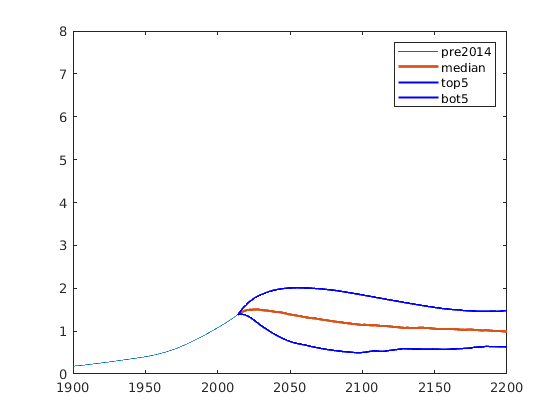


%plot(tspan, bline_params_results(:,end))
plot(tspan, median_vals, 'LineWidth', 2)
plot(tspan, top_five, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
plot(tspan, bot_five, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
legend("pre2014","median", "top5", "bot5")

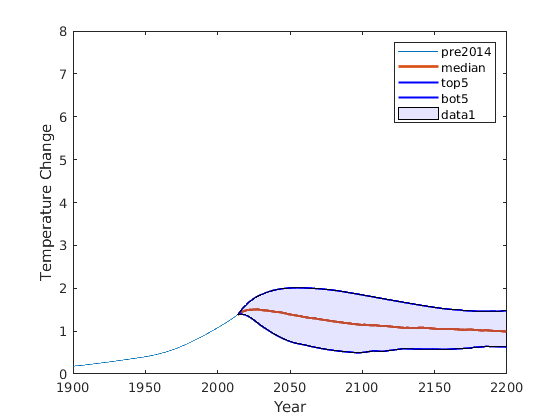

x2 = [tspan, fliplr(tspan)];
inBetween = [bot_five, fliplr(top_five)];
fill(x2, inBetween, 'b');
alpha(0.1);
xlabel('Year')
ylabel('Temperature Change')


%{

    x0    = 0.05;
    kappa = 0.2;
    delta = 0.5;
    beta  = 0.5;
    t_f   = 50;
    f_max = 6;
%}

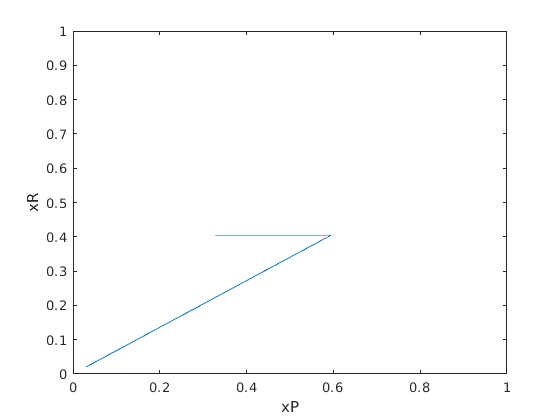

clf
plot(all_results.xPvals(:,25), all_results.xRvals(:,25))
xlabel("xP")
ylabel("xR")
ylim([0,1])
xlim([0,1])

xPvals = all_results.xPvals;
xRvals = all_results.xRvals;

median_vals_xP = quantile(xPvals', 0.5);
bot_five_xP    = quantile(xPvals', 0.05);
top_five_xP    = quantile(xPvals', 0.95);

median_vals_xR = quantile(xRvals', 0.5);
bot_five_xR    = quantile(xRvals', 0.05);
top_five_xR    = quantile(xRvals', 0.95);

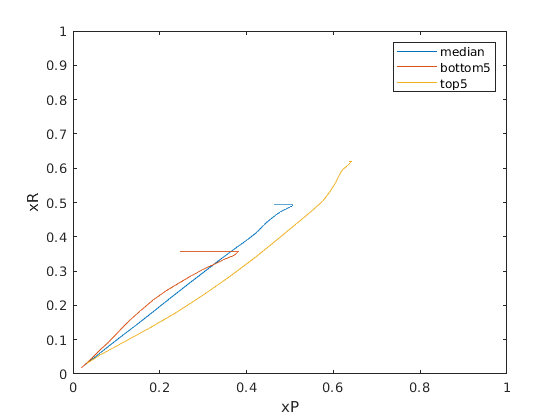

clf
plot(median_vals_xP, median_vals_xR)
hold on
plot(bot_five_xP, bot_five_xR)
plot(top_five_xP, top_five_xR)
xlabel("xP")
ylabel("xR")
ylim([0,1])
xlim([0,1])
legend("median", "bottom5", "top5")

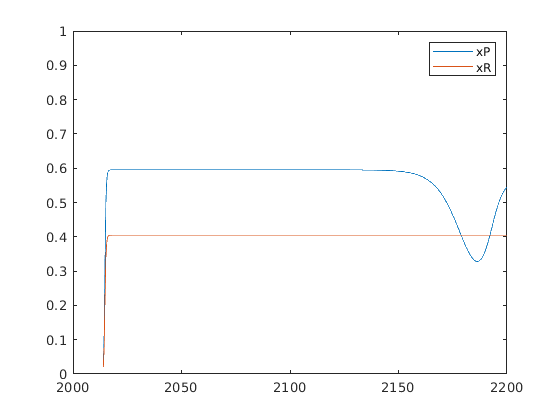

clf
plot(tspan, all_results.xPvals(:,25))
hold on
plot(tspan, all_results.xRvals(:,25))
legend("xP", "xR")
ylim([0,1])

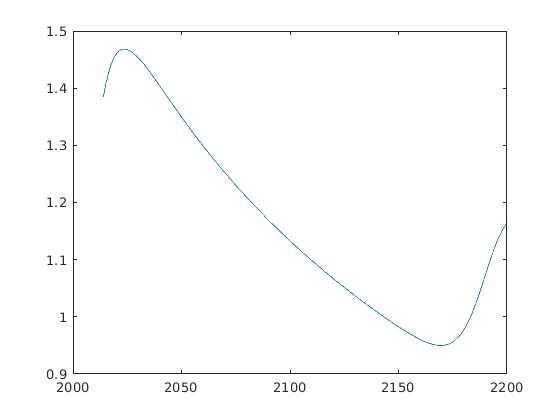

clf
plot(tspan, temperature_vals(:,25))